% EXPERIMENT 9
%% Exercise No:1
fprintf('EXERCISE Q1\n')

EXERCISE Q1


%% Step 1: Read an Image
disp('Step 1: Reading image...');

Step 1: Reading image...


img = imread("D:\Study\DYPU\SEM\sem7\ITWSM\lab\Interstellar-wallpaper-hd.jpg"); 

%% Step 2: Display Original Image
disp('Step 2: Display original image');

Step 2: Display original image


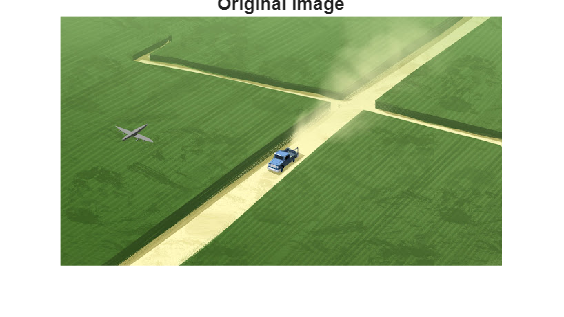

figure; imshow(img); title('Original Image');


%% Step 3: Convert RGB to Grayscale
disp('Step 3: Converting RGB to Grayscale');

Step 3: Converting RGB to Grayscale


grayImg = rgb2gray(img);

%% Step 4: Convert RGB to HSV
disp('Step 4: Converting RGB to HSV');

Step 4: Converting RGB to HSV


hsvImg = rgb2hsv(img);

%% Step 5: Display Grayscale and HSV
disp('Step 5: Displaying Grayscale and HSV images');

Step 5: Displaying Grayscale and HSV images


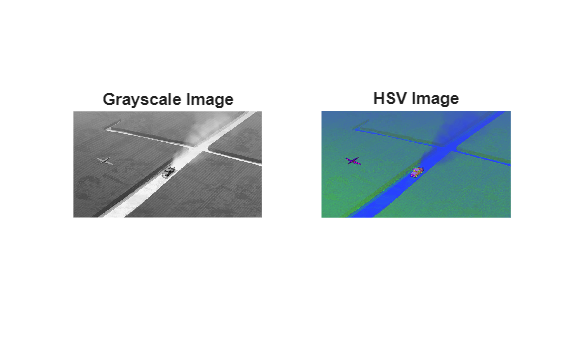

figure;
subplot(1,2,1); imshow(grayImg); title('Grayscale Image');
subplot(1,2,2); imshow(hsvImg); title('HSV Image');


%% Step 6: Resize Image to Half Size
disp('Step 6: Resizing image to half size');

Step 6: Resizing image to half size


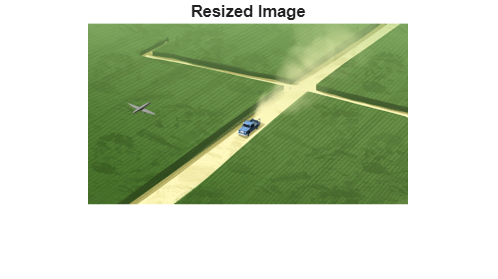

resizedImg = imresize(img, 0.5);
figure; imshow(resizedImg); title('Resized Image');


%% Step 7: Crop a Region of Interest
disp('Step 7: Cropping a region of interest');

Step 7: Cropping a region of interest


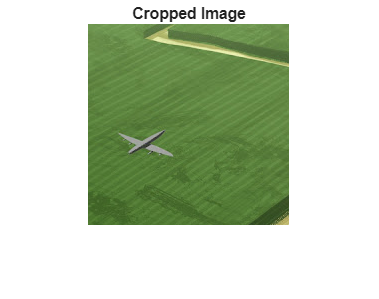

% Example crop rectangle: [x, y, width, height]
cropRect = [50 50 200 200]; % Adjust as needed
croppedImg = imcrop(img, cropRect);
figure; imshow(croppedImg); title('Cropped Image');


%% Step 8: Convert Cropped Image to Grayscale
disp('Step 8: Converting cropped image to grayscale');

Step 8: Converting cropped image to grayscale


croppedGray = rgb2gray(croppedImg);

%% Step 9: Normalize Grayscale Image
disp('Step 9: Normalizing grayscale image using mat2gray');

Step 9: Normalizing grayscale image using mat2gray


normalizedImg = mat2gray(croppedGray);

%% Step 10: Display Normalized Grayscale Image
disp('Step 10: Displaying normalized grayscale image');

Step 10: Displaying normalized grayscale image


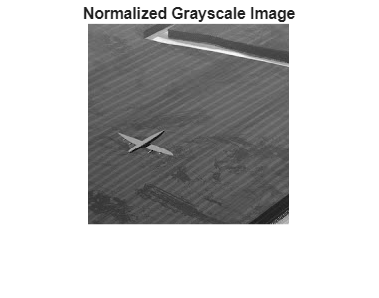

figure; imshow(normalizedImg); title('Normalized Grayscale Image');


%% Exercise No:2
fprintf('EXERCISE Q2\n')

EXERCISE Q2



%% Step 1: Load your own image
disp('Step 1: Reading your own image...');

Step 1: Reading your own image...


img2 = imread("D:\Study\DYPU\SEM\sem7\ITWSM\lab\Interstellar-wallpaper-hd.jpg"); 

%% Step 2: Display in Grayscale and HSV
disp('Step 2: Display grayscale and HSV images');

Step 2: Display grayscale and HSV images


grayImg2 = rgb2gray(img2);
hsvImg2 = rgb2hsv(img2);
figure;
subplot(1,2,1); imshow(grayImg2); title('Grayscale Image');
subplot(1,2,2); imshow(hsvImg2); title('HSV Image');


%% Step 3: Resize image to double size
disp('Step 3: Resizing image to double size');

Step 3: Resizing image to double size


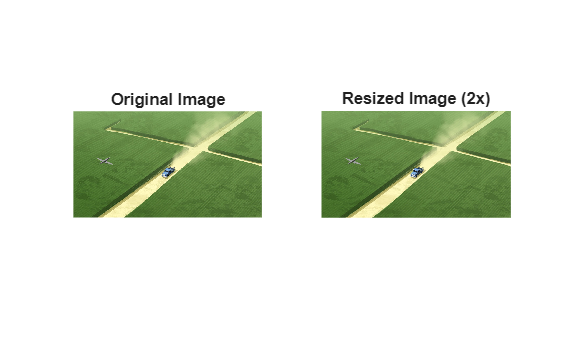

resizedImg2 = imresize(img2, 2); % 2x size
figure;
subplot(1,2,1); imshow(img2); title('Original Image');
subplot(1,2,2); imshow(resizedImg2); title('Resized Image (2x)');


%% Step 4: Crop a region of interest
disp('Step 4: Cropping image to extract object of interest');

Step 4: Cropping image to extract object of interest


% Example crop rectangle: [x, y, width, height]
cropRect2 = [50 50 200 200]; % Adjust for your object (face or item)
croppedImg2 = imcrop(img2, cropRect2);
figure; imshow(croppedImg2); title('Cropped Image');


%% Step 5: Normalize the cropped image
disp('Step 5: Normalizing cropped image and verifying intensity');

Step 5: Normalizing cropped image and verifying intensity


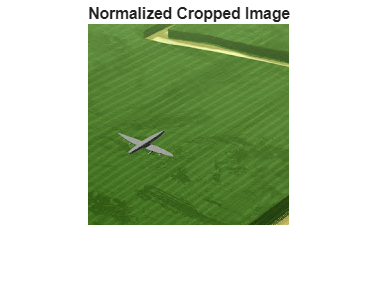

normalizedImg2 = mat2gray(croppedImg2);
figure; imshow(normalizedImg2); title('Normalized Cropped Image');


% Verify intensity range
minVal = min(normalizedImg2(:));
maxVal = max(normalizedImg2(:));
disp(['Minimum intensity = ', num2str(minVal)]);

Minimum intensity = 0


disp(['Maximum intensity = ', num2str(maxVal)]);

Maximum intensity = 1
